# Torsión en barras con perfiles cuadriculados

clc
clear all %#ok<*CLALL>

mfilePath = mfilename('fullpath');
if contains(mfilePath,'LiveEditorEvaluationHelper')
    mfilePath = matlab.desktop.editor.getActiveFilename;
end
[pathstr,~,~] = fileparts(mfilePath);
cd(pathstr)

PYTHON_EXEC="python.exe";
profiles_dir = "perfiles";
profile_files = get_profile_files(profiles_dir);

% Para MATLAB (R2022b) New Desktop Plugin 
s = settings;
s.matlab.appearance.figure.GraphicsTheme.TemporaryValue= 'light';
 

**Crear nuevo perfil**

new_profile_name = "profile_1";
ncells = 10;
if ~exist(profiles_dir, 'dir')
   mkdir(profiles_dir)
end
output = sprintf("%s/%s", profiles_dir, new_profile_name);
system(sprintf("%s profile_designer.py %s %d", PYTHON_EXEC, output, ncells));

python.exe: can't open file 'C:\\Users\\josue\\OneDrive - Universidad de los andes\\202320\\IMEC 4600-01 M╔TODOS DE DIFERENCIAS FINITAS PARA ECUACIONES DIFERENCIALES\\Talleres\\Taller 4\\profile_designer.py': [Errno 2] No such file or directory 


if ~contains(profile_files, new_profile_name)
    profile_files(end+1) = sprintf("%s.pbm", new_profile_name);
end
 

**Seleccionar perfil**

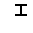

profile_name = "i.pbm";
profile_file = sprintf("%s/%s", profiles_dir, profile_name);
profile_data = imread(profile_file);
imshow(imresize(profile_data, 3, "nearest"))

**Parámetros**

params = struct();
params.T = 10; % torque [N*mm]
params.W = 10; % ancho perfil [mm]
params.L = 100; % longitud perfil [mm]
params.G = 80; % modulo de rigidez cortante material [GPa]
params.h = 0.1; % (dx) tamaño de malla [mm]
 

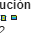


 
ts = torsionsys(~profile_data, params);
ts = ts.setupsystem();
ts = ts.solvesystem();
ts.showPhi()

function profile_files = get_profile_files(profiles_dir)
    profile_files = struct2cell(dir(sprintf("%s/*.ppm",profiles_dir)));
    profile_files = string(profile_files(1,:));
end